%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% function2verilog:
% Generate the Verilog code for the non-linear function. (Can only generate
% the the Verilog for 2's complement notation).
%
% Written by Huifeng Zhu (zhuhuifeng@wustl.edu) @ 11/15/20. 
% For ESE461 using only.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear
clc
close all

% User input
resulotion = 8; % number of bits
fixed_point = [5,6]; % the position of the fixed point. 
                     % This means the fined point is between 4th and 5th.
target_function = @tanh; % the name of the target function
                         % There is no general function called sigmoid in
                         % Matlab. So need to write a sigmoid function if
                         % want to generate it.
output_file_name = "tanh.v"; % the name of the output file

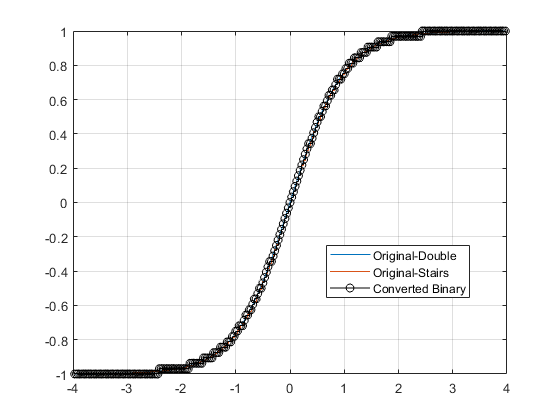

% Calculate the function;
maximum_X = (2^(resulotion-1)-1)*(1/2^fixed_point(1));
X_double = -maximum_X: 1/2^fixed_point(1): maximum_X;
Y_double = target_function(X_double);
plot(X_double,Y_double,'-');
hold on;
stairs(X_double,Y_double);
hold on

% Convert double to 2' complement binary
X_double_int = X_double.*2^fixed_point(1);
Y_double_int = Y_double.*2^fixed_point(1);
X_binary = dec2bin(X_double_int,resulotion); % Starting in R2020a, the dec2bin function converts 
                                             % negative numbers using their two's complement binary values.
Y_binary = dec2bin(Y_double_int,resulotion);
X_binary = X_binary(:,end-resulotion+1:end); % Truncate the binary code.
Y_binary = Y_binary(:,end-resulotion+1:end);

% Check the converted binary
Y_available = -1: 1/2^(fixed_point(2)-1): 1;
Y_double_check = zeros(size(Y_double));
for i = 1:length(Y_double)
    [v, index]=min(abs(Y_available(:)-Y_double(i)));
    Y_double_check(i) = Y_available(index);
end
stairs(X_double,Y_double_check,'kO-');
legend(["Original-Double", "Original-Stairs","Converted Binary"],"Location","best");
grid on

% Generate the Verilog code
fid = fopen(output_file_name,'w');
fprintf(fid,'module tanh(clk,rst,X,Y); // Generated by Matlab script function2verilog\n');
fprintf(fid,'\tinput clk, rst;\n');
fprintf(fid,['\tinput [',num2str(resulotion-1),':0] X;\n']);
fprintf(fid,['\toutput reg [',num2str(resulotion-1),':0] Y;\n\n']);
fprintf(fid,'\talways @ (posedge clk) begin\n');
fprintf(fid,'\t\tif (!rst) Y <= 0;\n');
fprintf(fid,'\t\telse begin\n'); 
fprintf(fid, '\t\t\tcase(X)\n');
for i = 1 : length(Y_double)
    line = [num2str(resulotion),'''b',X_binary(i,:),' : Y <= ',num2str(resulotion),'''b',Y_binary(i,:),';'];
    fprintf(fid,'\t\t\t\t%s\n',line);
end
fprintf(fid, ['\t\t\t\tdefault : Y <= ',num2str(resulotion),'''b0;\n']);
fprintf(fid,'\t\t\tendcase\n');
fprintf(fid,'\t\tend\n');
fprintf(fid,'\tend\n');
fprintf(fid,'endmodule //tanh');